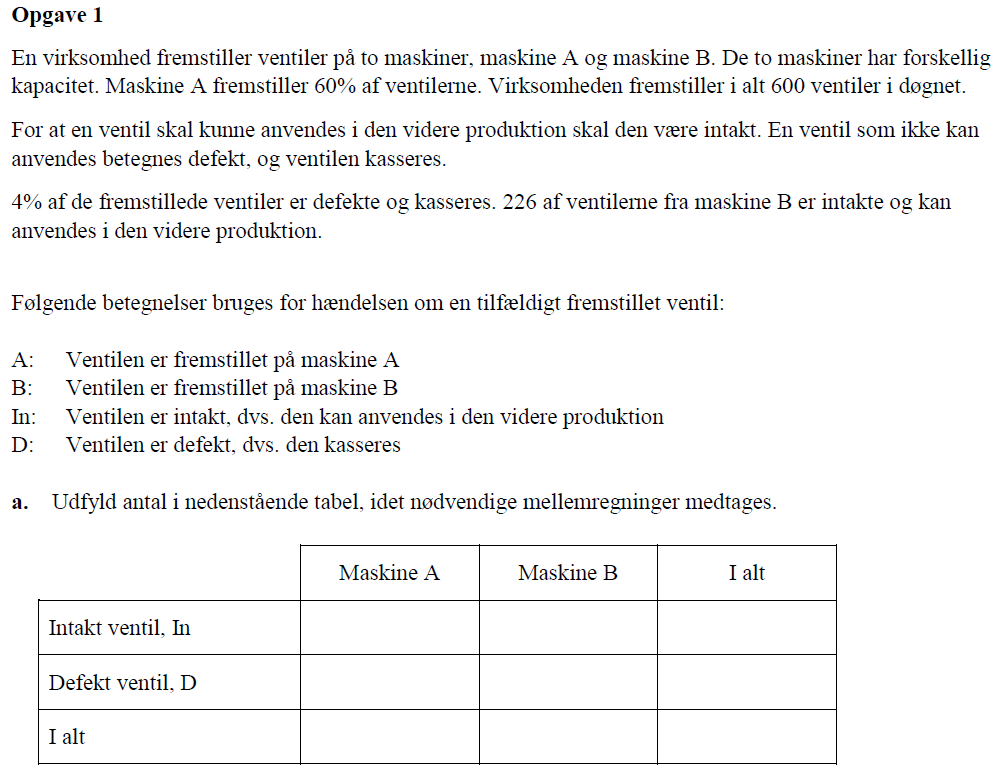

tot = 600

tot = 600

A_tot = 0.6 * tot

A_tot = 360


B_tot = 0.4 * tot

B_tot = 240

B_int = 226

B_int = 226

B_def = B_tot - B_int 

B_def = 14


tot_def = 0.04 * tot

tot_def = 24


A_def = tot_def - B_def

A_def = 10

A_int = A_tot - A_def

A_int = 350


tot_int = A_int + B_int

tot_int = 576


Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'Int - intakt', 'Def - defekt', 'I alt'};
table([A_int; A_def; A_tot], [B_int; B_def; B_tot], [tot_int; tot_def; tot], VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
                    Maskine A     Maskine B    I alt
                    _________    __________    _____

    Int - intakt       350          226         576 
    Def - defekt        10           14          24 
    I alt              360          240         600 


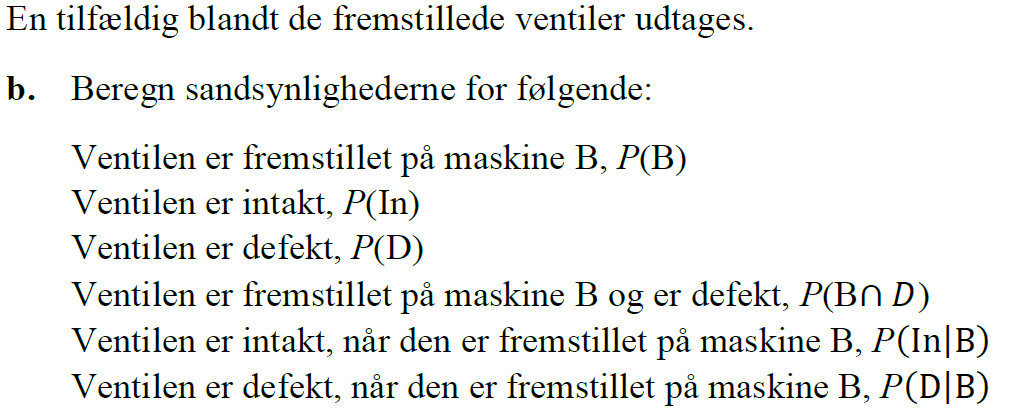

P_B = B_tot/tot

P_B = 0.4000

P_int = tot_int/tot

P_int = 0.9600

P_def = tot_def/tot

P_def = 0.0400

P_B_fel_int = B_def / tot

P_B_fel_int = 0.0233

P_int_giv_B = B_int/B_tot

P_int_giv_B = 0.9417

P_def_giv_B = 1 - P_int_giv_B % eller P_def_giv_B = B_def / B_tot

P_def_giv_B = 0.0583

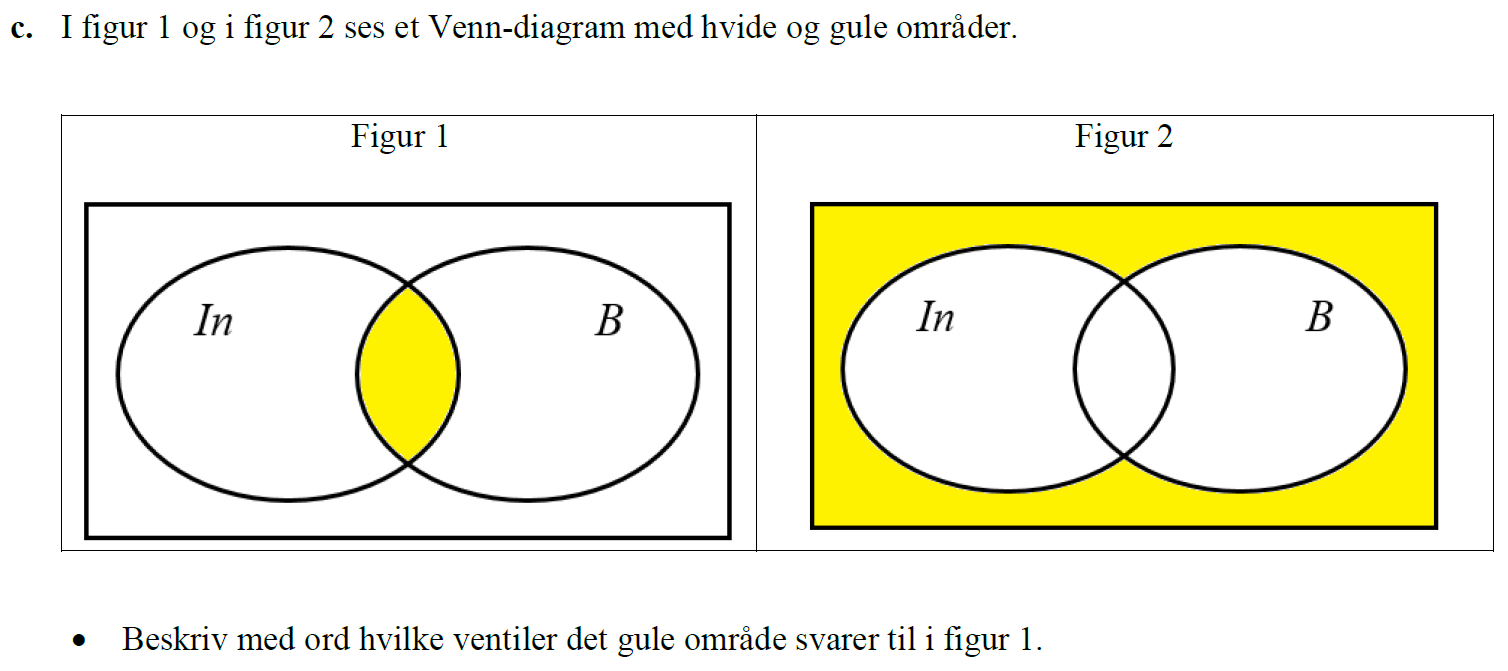

Det svare til mængden af intakte ventiler som maskine B laver.

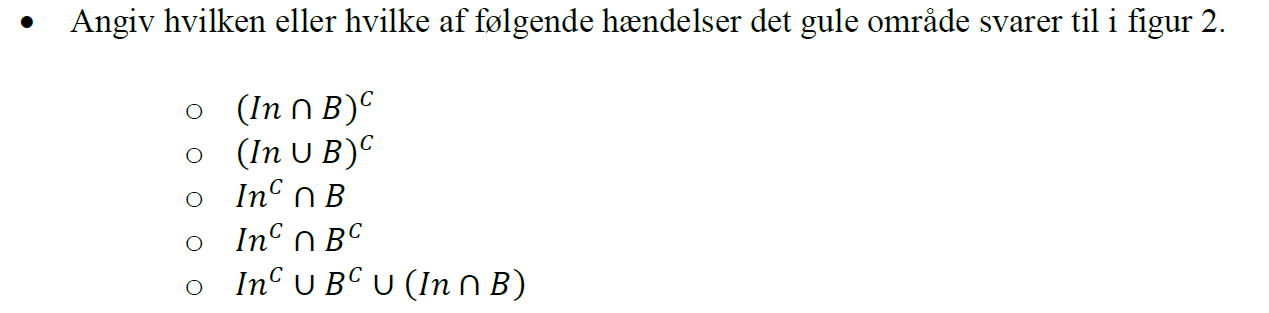

Dette svare til $(In \cap B)^C$ og $In^C \cap B^C$

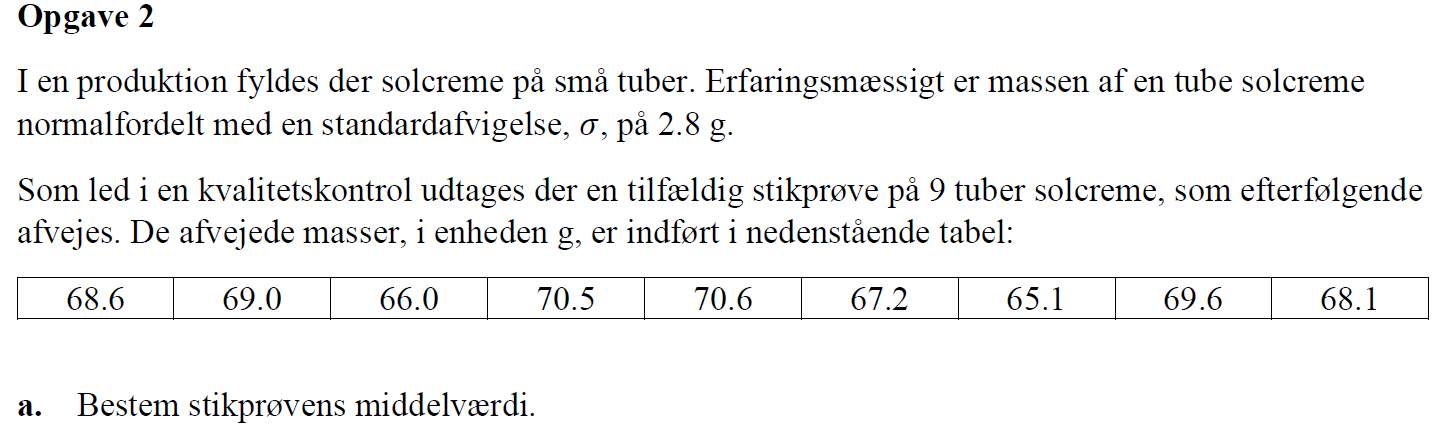

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22E\Data_M4STI1_2022E.xlsx"); %indlæser vores data
sol_data = data(1:9,1);
std = 2.8; %g

y_bar = mean(sol_data)

y_bar =          68.3


Det ses at stikprøven er en 2 sidet fordeling og vi kender spredningen derfor vælges en Z fordeling.

n = length(sol_data)

n =      9


z_a_2 = norminv(1-0.025)

z_a_2 =          1.96


konf_95 = z_a_2 * std / sqrt(n)

konf_95 =        1.8293


[y_bar-konf_95 , y_bar + konf_95]

ans =        66.471       70.129


Den beskriver at middelværdien af stik prøven($\bar y \pm2.15\ g$) ligger inden for 2,15 gram af populationens middelværdi 

Et 95%-konfidensinterval for middelværdien angiver det interval, hvor vi med 95% sikkerhed finder populationens middelværdi.

Vi prøver os frem med forskellige værdier

syms n_test

eq = 1.5 == z_a_2 * std / sqrt(n_test);
sol = solve(eq, n_test);
vpa(sol,4)

$$ans = 13.39$$

Således skal der være en stikprøvestørrelse på 14

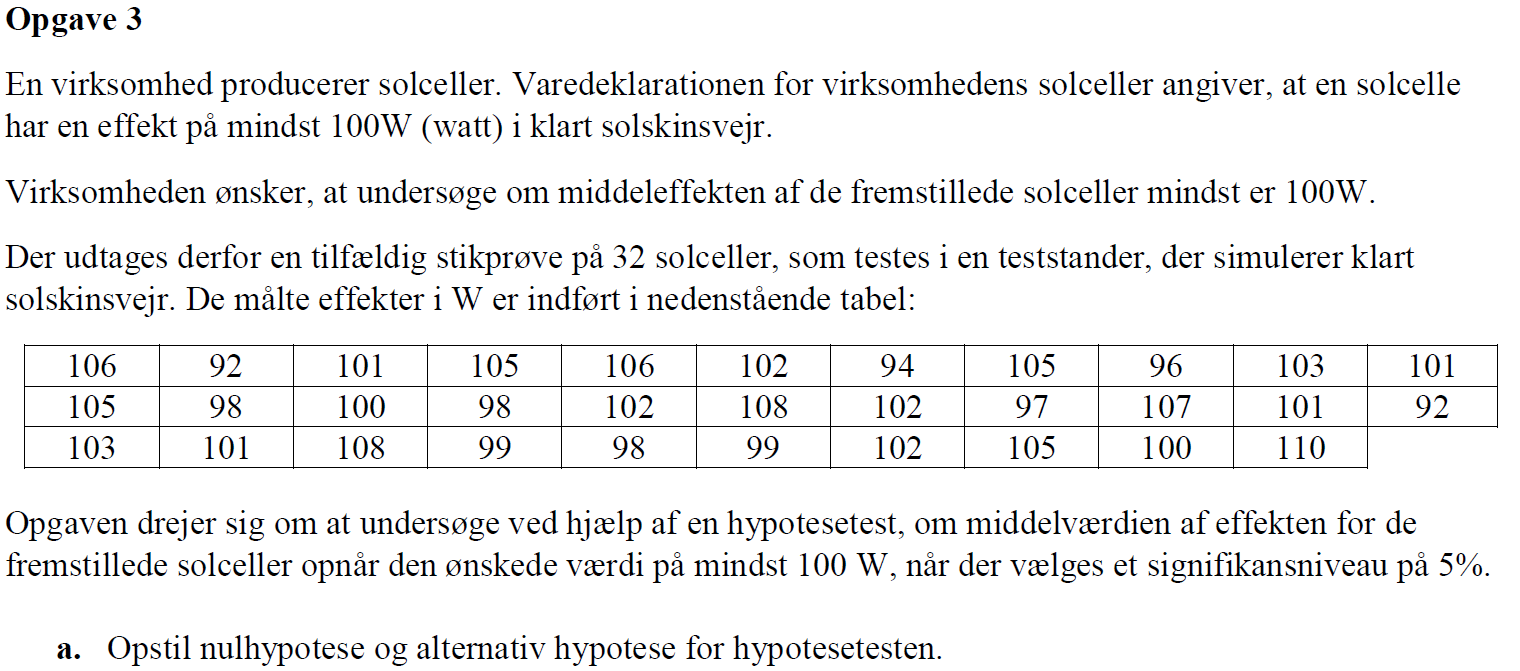

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22E\Data_M4STI1_2022E.xlsx"); %indlæser vores data
sol_celle_data = data(:,4);
mu = 100; %W
n = length(sol_celle_data)

n =     32



$$H_0:\ \mu  = 100\ W \\
H_a:\ \mu < 100\ W$$


Hvis middelværdien er ens med middelværdien af populationen kan vi ikke forkaste vores hypotese. det bemærkes at testen er 1 sidet

**b. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.**

Der benyttes en t fordeling da vi har en stikprøve på en lille til mellem størrelse og vi ikke kender variansen. 

Dermed benyttes ligningen for teststørrelsen som:

**c. Bestem den kritiske værdi og angiv det kritiske område for testen.**

df = n -1;
alpha = 0.05 % da testen er 1 sidet

alpha =          0.05


t_c = tinv(0.05, df) 

t_c =       -1.6955


**d. Beregn teststørrelsens (teststatistikkens) værdi, idet nødvendige mellemregninger medtages.**

y_bar = mean(sol_celle_data)

y_bar =        101.44


var = var(sol_celle_data)

var =        20.125


s = std(sol_celle_data)

s =        4.4861


t_0 = (y_bar - mu) / (s/sqrt(n))

t_0 =        1.8127


**e. Konkluder på hypotesetesten.**


$$t_0 < t_c$$


t_0 > t_c

ans = logical
   1


Det ses således at $t_0(1,81)$ er mindre end $t_c(-1,70)$ og vi er således ikke ude i det kritiske område. Dermed kan vi ikke forkaste vore $H_0$ hypotese

**f. Hvilken antagelse er der foretaget for at udføre hypotesetesten?**

**Er antagelsen rimelig?**

Det er antaget at populationen er normalt fordelt og at vores stikprøve er repressentativ for populationen. Her er brugt den centrale grænseværdisætning da stikprøvestørrelsen er størrer end 30

**g. Lav et boxplot, et histogram og et normalfordelingsplot for de målte data.**

**Kommenter de tre plots.**

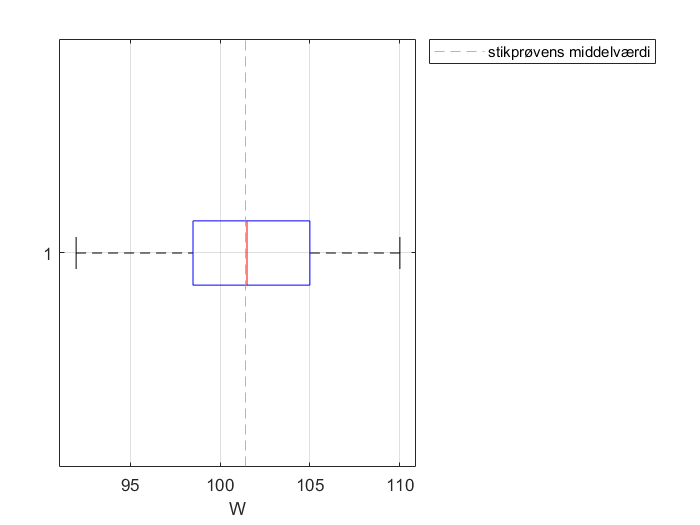

figure(1)
X = sol_celle_data;
md = median(X); % finder medianen
q1 = prctile(X, 25); % finder første kvatil ved at finde data punkt ved 25%
q3 = prctile(X, 75); % finder første kvatil ved at finde data punkt ved 75%
Q = prctile(X, [25, 50, 75]); % finder alle 3 kvatiler ud fra 25% 50% 75% Q2 = medianen
Q = quantile(X, 3); % finder alle 3 kvatiler ud fra procent

boxplot(X,'Orientation',"horizontal")
xline(y_bar, '--', color='g', DisplayName='stikprøvens middelværdi')
xlabel('W')
legend('location', 'northeastoutside')
grid("on")

Boxplottet har en median på 101.5, som stort set er sammenfaldende med middelværdien på 101.4.

Det interkvartile range ligger pænt symmetrisk omkring medianen. Med nedre kvartil på 98.5 og øvre kvartil på 105.0. Den øvre del er lidt bredere end den nedre del.

Den nedre kost er lidt længere end den øvre. Dvs. fordelingen af data er lidt venstre skæv.

Der er ingen outliers.

Dvs. data kommer fra en stort set pæn fordeling

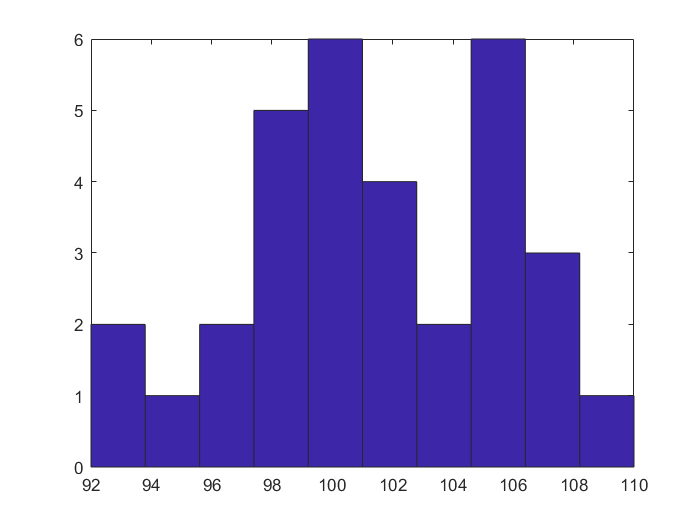

figure(2)
hist(sol_celle_data,10)

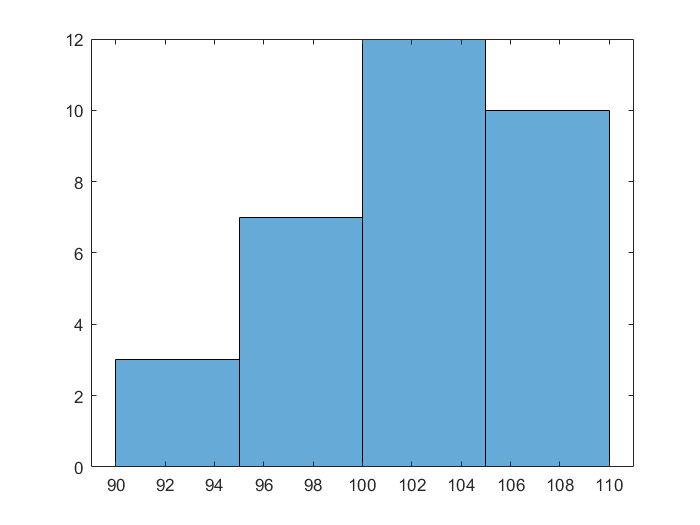

histogram(sol_celle_data, [90:5:110])

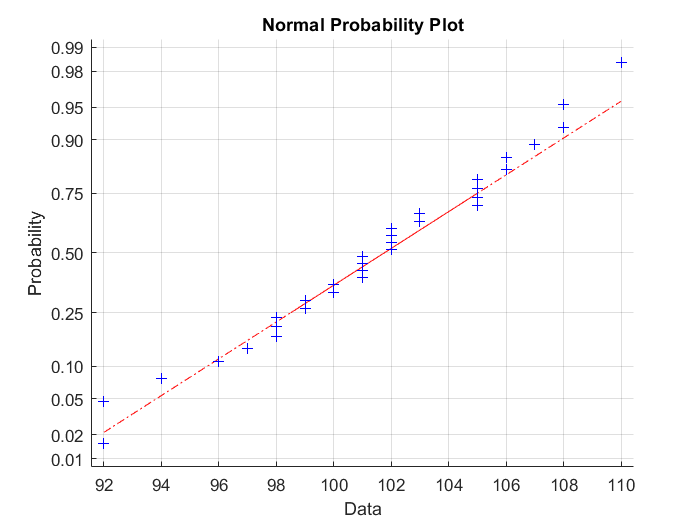

figure(3)
normplot(sol_celle_data)

Samlede set ligger vores middelværdi pænt i quitil 2 har en fin histogram form dog med nogle afvigelser omkring 104. Normalplottet sølger en find fordeling der måske er meget lidt skæv i toppen. alt i alt er det en fin model.

Boxplot, histogram og normalfordelingsplot viser alle, at stikprøven kommer fra en pæn fordeling, der godt kunne ligne en normalfordeling. Så også her er kravet for at den centrale græseværdi sætning gælder,opfyldt.

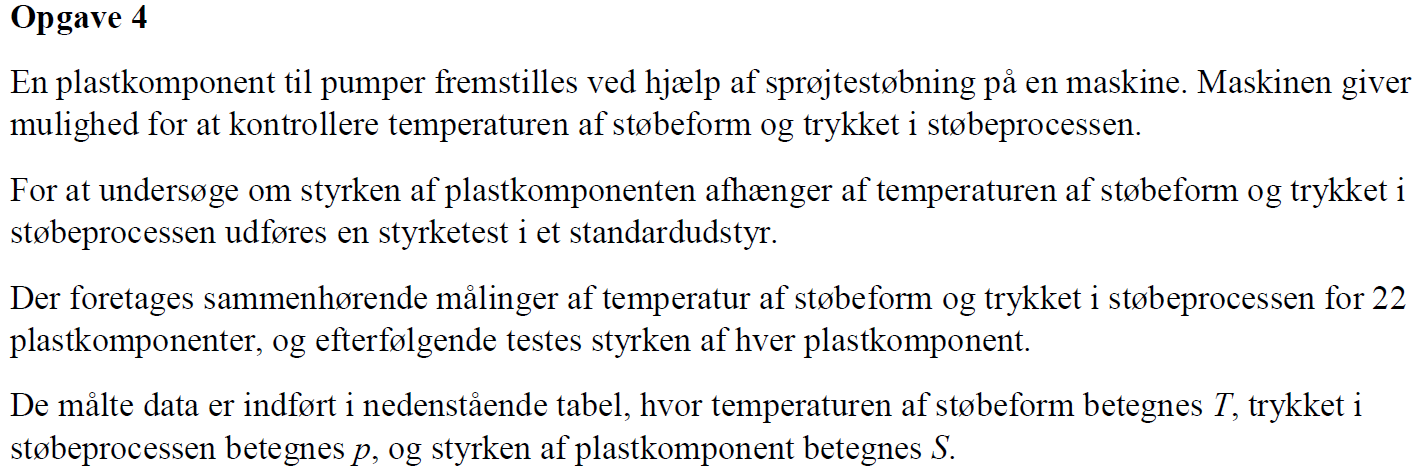

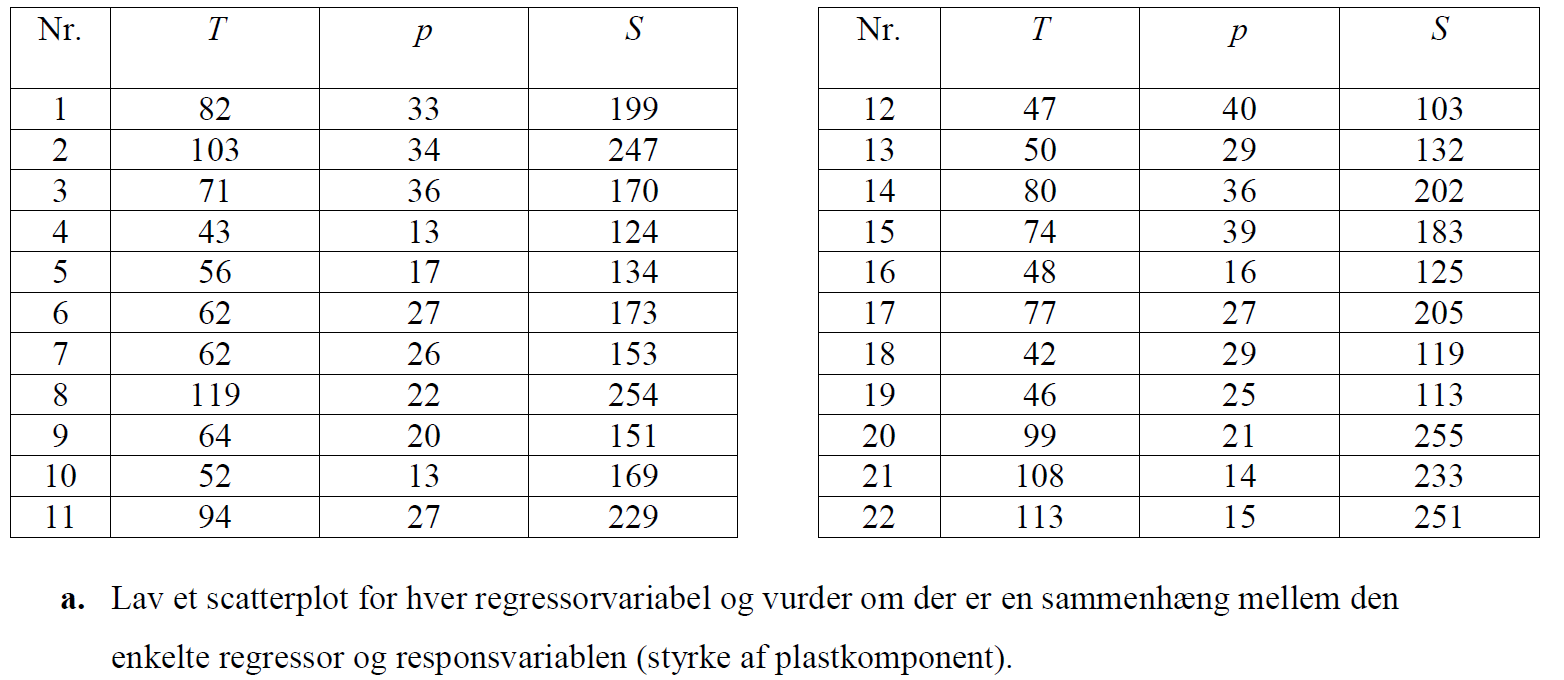

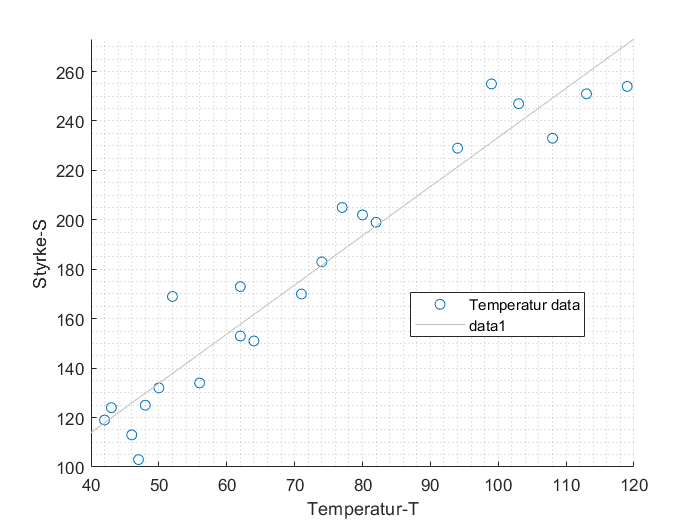

T = data(1:22,7);
p = data(1:22,8);
S = data(1:22,9);



figure(4)
scatter(T, S, DisplayName='Temperatur data')
lsline
xlabel('Temperatur-T')
ylabel('Styrke-S')
grid('minor')
legend('Location','best')

For temperaturen ses en klar tendens at når temperaturen stiger så stiger styrken. dette ses ved at punkterne ligger sig pænkt lang en ret linje op ad

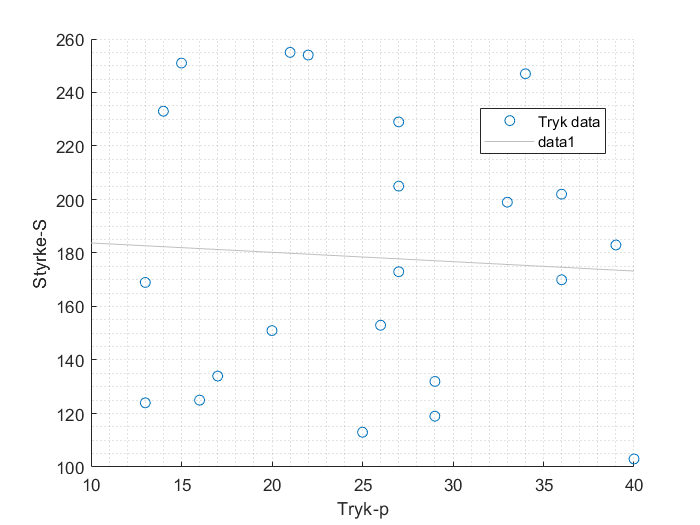

figure(5)
scatter(p, S, DisplayName='Tryk data')
lsline
xlabel('Tryk-p')
ylabel('Styrke-S')
grid('minor')
legend('Location','best')

På plottet ser resultatrne for styrken grundet trykket lidt telfældige ud, og der ser ikke ud til at være en påvirkning af trykket på styrken.

b. Lav en multipel lineær regressionsanalyse, der beskriver styrke af plastkomponent (S) som funktion af temperatur af støbeform (T) og af trykket i støbeprocessen (p). Opskriv regressionsligningen.

mdl1 = fitlm([T, p],S)

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)     37.464      13.869      2.7012      0.014153
    x1              1.9884     0.12955      15.349    3.6695e-12
    x2             -0.1177     0.36857    -0.31934       0.75295


Number of observations: 22, Error degrees of freedom: 19
Root Mean Squared Error: 14.5
R-squared: 0.926,  Adjusted R-Squared: 0.918
F-statistic vs. constant model: 118, p-value = 1.9e-11

Vi får således ligningen $S(T,p) = 37,464 + 1,9884 \cdot T - 0,1177 \cdot p$

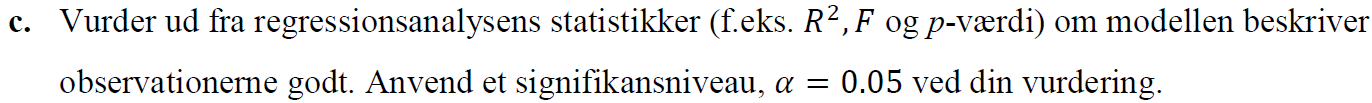

Vi får en $R_{adj}
$ værdi på 0,918 hvilket vil sige at vore ligning beskriver virkligheden fint nok, p-værdien for $b_1$ er $3,67*10^{-12}$ og er derfor godt inden for vores signifikansnivue (5%), $b_0$ ligger også inden for men $b_2$ er meget høj og passer derfor dårligt til modellen. denne parameter bør derfor fjernes fra modellen.

**Løsningens vudering**

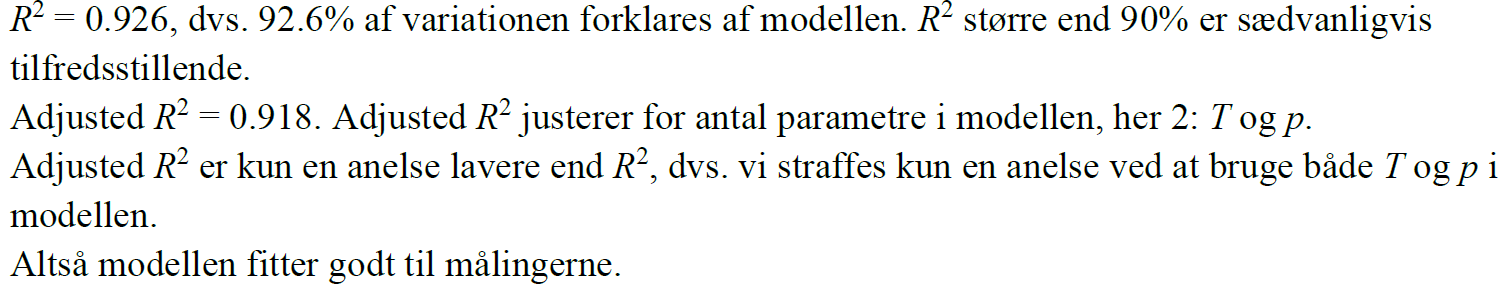

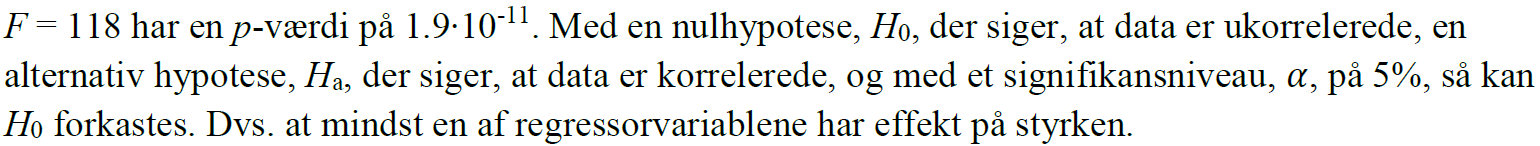

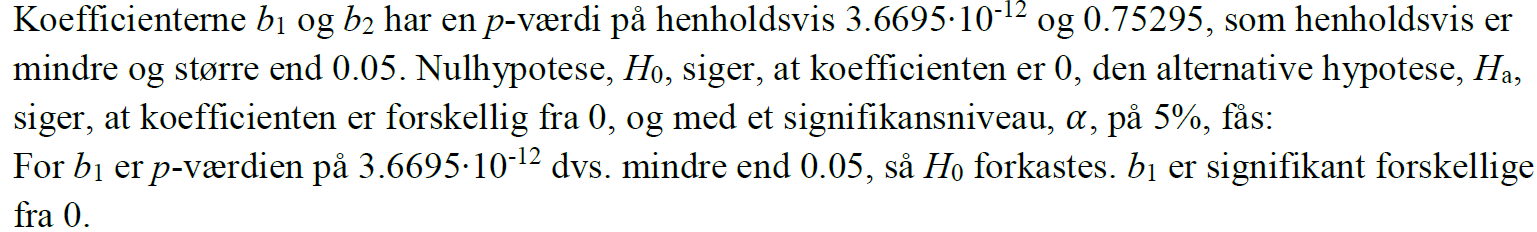

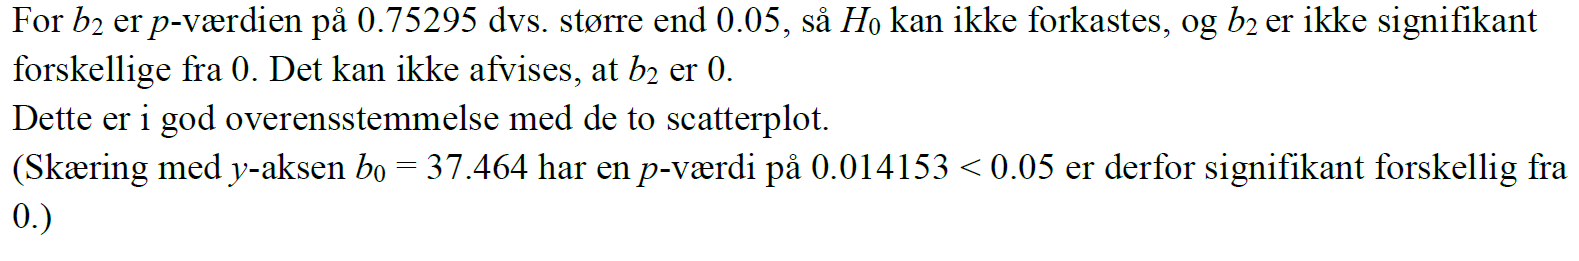

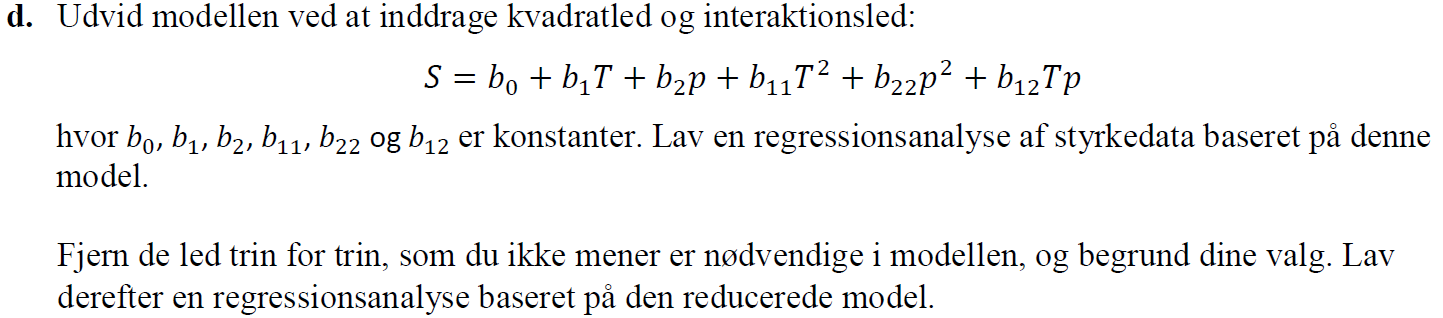

% T_2 = T.^2;
% p_2 = p.^2;
% TP = T .* p;
% 
% mdl2 = fitlm([T, p, T_2, p_2, TP],S)
mdl2 = fitlm([T, p],S, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2')

mdl2 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2 + x2^2

Estimated Coefficients:
                    Estimate        SE        tStat       pValue 
                   __________    ________    ________    ________

    (Intercept)        23.082      53.183     0.43401     0.67007
    x1                  2.913      1.2198      2.3882    0.029607
    x2                -1.4558       2.455    -0.59299     0.56148
    x1:x2            0.028193    0.015829      1.7811    0.093885
    x1^2           -0.0099556    0.006671     -1.4924     0.15506
    x2^2            -0.017189    0.041697    -0.41224     0.68563


Number of observations: 22, Error degrees of freedom: 16
Root Mean Squared Error: 12.6
R-squared: 0.953,  Adjusted R-Squared: 0.938
F-statisti

Her ses den største p værdi der overskrider vores significans nivue at være $p^2$ denne fjærnes og der prøves igen

% mdl3 = fitlm([T, p, T_2, TP], S)
mdl3 = fitlm([T, p],S, 'y ~ x1 + x2 + x1^2 + x1:x2')

mdl3 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    _______    ________

    (Intercept)       32.061       47.319    0.67754     0.50718
    x1                2.9509       1.1862     2.4876    0.023536
    x2               -2.3605        1.073       -2.2    0.041926
    x1:x2           0.028396      0.01543     1.8403    0.083248
    x1^2           -0.010199    0.0064805    -1.5738     0.13396


Number of observations: 22, Error degrees of freedom: 17
Root Mean Squared Error: 12.3
R-squared: 0.952,  Adjusted R-Squared: 0.941
F-statistic vs. constant model: 84.5, p-value = 5.51e-11

Her ses den største p værdi der overskrider vores significans nivue at være $T^2$ denne fjærnes og der prøves igen

% mdl4 = fitlm([T, p, TP], S)
mdl4 = fitlm([T, p],S, 'y ~ x1 + x2 + x1:x2')

mdl4 = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)      95.338     25.955     3.6732    0.0017394
    x1               1.1594    0.34721     3.3393    0.0036505
    x2              -2.7413     1.0874    -2.5211      0.02135
    x1:x2          0.037575    0.01486     2.5286     0.021017


Number of observations: 22, Error degrees of freedom: 18
Root Mean Squared Error: 12.8
R-squared: 0.945,  Adjusted R-Squared: 0.936
F-statistic vs. constant model: 103, p-value = 1.55e-11

Vi har nu at alle vores p værdier er inden for sicnificans nivuet og vi får ligningen


$$S(T,p) = 95,338 + 1,1594 \cdot T - 2,7413 \cdot p + 0,03758 \cdot Tp$$
 

Det ses at denne model har en bedre $R_{adj} = 0,936
$ og derfor burde passe bedre som model.

e. Opskriv ligningen for din foretrukne model.


$$S(T,p) = 95,338 + 1,1594 \cdot T - 2,7413 \cdot p + 0,03758 \cdot Tp$$


f. Undersøg om der er ”unormale” datapunkter, dvs. løftestangspunkter, outliers, indflydelsespunkter. Svaret skal begrundes.

% plot(mdl4)
lev = mdl4.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen
rst = mdl4.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3

c = 3; %antal regressor variable
n = length(rst); %antalt observationer
lev_limit = 2 * (c +1 )/ n

lev_limit =       0.36364


find(lev > lev_limit)

ans =      2
    12
    22


Punkterne 2, 12 og 22 er således størrer en vores grænse på 0,36364 og er dermed løfte punbkter

find(abs(rst) > 3)


ans =

  0×1 empty double column vector



Der findes ingen residualer der er størrer end 3 og dermed ingen outliers

Et punkt skal være både et løftestangspunkt og outlier for at være et indflydelsespunkt. Der er derfor ingen indflydelsespunkter.

nr = (1:length(S))';
disp(table(nr, T, p, S, lev, rst))

    nr     T     p      S       lev         rst   
    __    ___    __    ___    ________    ________

     1     82    33    199     0.11515    -0.21209
     2    103    34    247     0.38355    -0.59984
     3     71    36    170     0.11802    -0.40688
     4     43    13    124     0.29958    -0.60103
     5     56    17    134     0.12149      -1.311
     6     62    27    173    0.057372      1.3934
     7     62    26    153    0.055422    -0.27535
     8    119    22    254     0.22328     -1.6049
     9     64    20    151    0.070922    -0.95426
    10     52    13    169     0.21749      2.3244
    11     94    27    229     0.10412     0.26712
    12     47    40    103     0.45297    -0.81776
    13     50    29    132     0.11767     0.30004
    14     80    36    202    